PMR3523 Controle Moderno

Entrega 2 - Posicionamento Dinâmico de Navios

Ângelo Bianco Yanagita - 6649978

Diôgo Cavalcante Lopes - 11180872

set(groot,'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex');  
set(groot, 'defaultLegendInterpreter','latex');

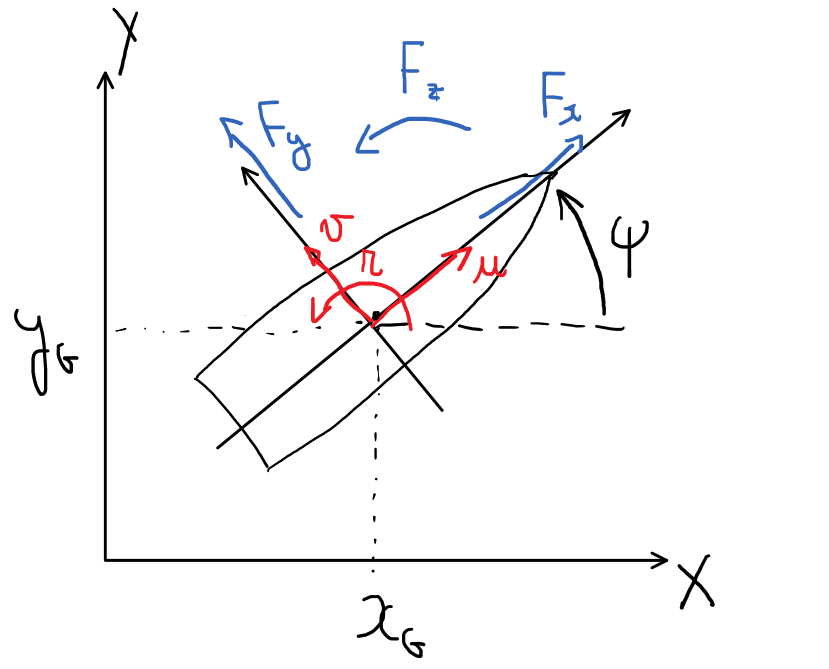

As equações utilizadas são:


$$(1) \; \dot{x}_G=u\cdot cos(\psi)-v\cdot sin(\psi)\\
(2) \; \dot{y}_G=u\cdot sin(\psi)+v\cdot cos(\psi)\\
(3) \; \dot{\psi}=r \\
(4) \; (M+M_{11})\dot{u}-(M+M_{22})v\cdot r -(M\cdot x_G + M_{26})r^2 = F_x \\
(5) \; (M+M_{22})\dot{v}+(M\cdot x_G+M_{26})\dot{r} +(M + M_{11})u\cdot r = F_y \\
(6) \; (I_Z+M_{66})\dot{r}+(M\cdot x_G+M_{26})(\dot{v}+u\cdot r) + (M_{22} - M_{11})u\cdot v = M_z
$$


Sendo as variáveis:

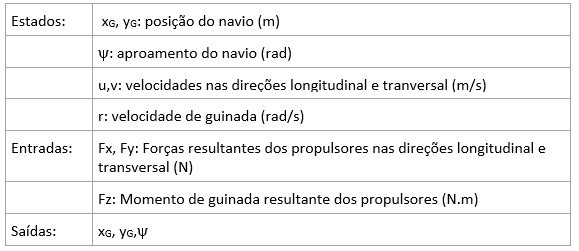


$$\begin{array}{l}
x={\left\lbrack \begin{array}{cccccc}
x_g  & y_g  & \psi \; & u & v & r
\end{array}\right\rbrack }^T \\
u={\left\lbrack \begin{array}{ccc}
F_x  & F_y  & F_z 
\end{array}\right\rbrack }^T \\
y={\left\lbrack \begin{array}{ccc}
x_g  & y_g  & \psi \;
\end{array}\right\rbrack }^T 
\end{array}$$


Considerando os parâmetros do navio de suporte à plataforma Maersk Handler:  

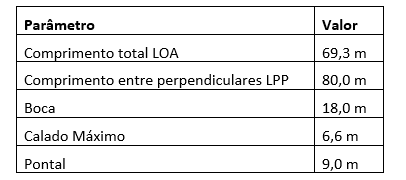

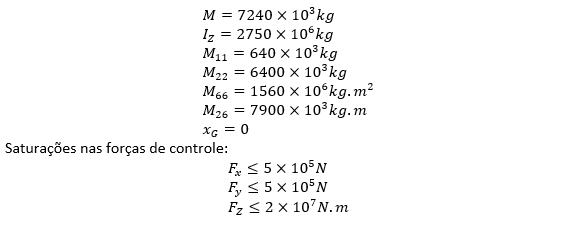

m = 7240e3;
izz = 2750e6;
m11 = 640e3;
m22 = 6400e3;
m66 = 1560e6;
m26 = 7900e3;

E as condições de linearização:


$$x_G^*=u^*=y_G^*=v^*=\psi^*=r^*=0$$



$$F_x=F_y=M_z=0$$


Utilizando o método de linearização dinâmica com Série de Taylor, obtém-se as seguintes matrizes do espaço de estados:


$$\begin{array}{l}
\delta \dot{x} =A\delta x\left(t\right)+B\delta u\left(t\right)\\
\;\delta y=C\delta x\left(t\right)+D\delta u\left(t\right)\;
\end{array}$$


onde:


$$\delta x= \left[\matrix{\delta x_G\cr
             \delta y_G\cr
             \delta \psi\cr
              \delta u\cr
              \delta v\cr
               \delta r}\right]$$
  
$$\delta \dot{x}= \left[\matrix{\delta u\cr
             \delta v\cr
             \delta r\cr
              \delta \dot{u}\cr
              \delta \dot{v}\cr
               \delta \dot{r}}\right]$$
 
$$\delta u= \left[\matrix{F_x\cr
             F_y\cr
               M_z}\right]$$
 
$$\delta y= \left[\matrix{x_G\cr
             y_G\cr
               \psi}\right]$$



$$D=\left[ \begin{array}{c}
0
\end{array}\right]$$



$$A_{6x6}=\left\lbrack \begin{array}{cccccc}
0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & 0\\
0 & 0 & 0 & 0 & 0 & 1\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack$$
 
$$B_{6x3}=10 ^{-10}\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
0 & 0 & 0\\
0 & 0 & 0\\
1269  & 0 & 0\\
0 & 734 & -1,345\\
0 & -1,345 & 2,323
\end{array}\right\rbrack$$
 
$$C_{3x6}=\left\lbrack \begin{array}{cccccc}
1 & 0 & 0 & 0 & 0 & 0\\
0 & 1 & 0 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0 & 0
\end{array}\right\rbrack$$
 

m = 7240e3;
izz = 2750e6;
m11 = 640e3;
m22 = 6400e3;
m66 = 1560e6;
m26 = 7900e3;

a=395/682;
b=79/43100;
c=a*b;
d=a/(431*10^7);
e=1/(1364*10^4*0.9989);
f=d/0.9989;
g=b*e;
h=b*f;
i=(1/431*10^7)+h;

A = [0 0 0 1 0 0
     0 0 0 0 1 0
     0 0 0 0 0 1
     0 0 0 0 0 0
     0 0 0 0 0 0
     0 0 0 0 0 0];
 
B = [0 0 0 
    0 0 0
    0 0 0
    1.269e-07 0 0
    0 e -f
    0 -g i];

C = [1 0 0 0 0 0
    0 1 0 0 0 0
    0 0 1 0 0 0
    0 0 0 0 0 0
    0 0 0 0 0 0
    0 0 0 0 0 0];

D = 0;

t = 0:0.01:100;
i = 1; % contador para os gráficos

# Teste 1

## 
$$F_x =2\ldotp 5*{10}^{5\;} \;\;N;F_{y\;} =0\;;M_z =0$$


fx = 2.5e5;
fy = 0;
mz = 0;
[xg_linear, yg_linear, psi_linear] = sim_linear(t);

[xg_non_linear, yg_non_linear, psi_non_linear] = sim_non_linear(t);

Found algebraic loop containing: 
nonlinear_system_angelo/equation 5/Add
nonlinear_system_angelo/equation 5/Gain
nonlinear_system_angelo/equation 6/Add2
nonlinear_system_angelo/equation 6/Product3
nonlinear_system_angelo/equation 6/Add
nonlinear_system_angelo/equation 6/Gain
nonlinear_system_angelo/equation

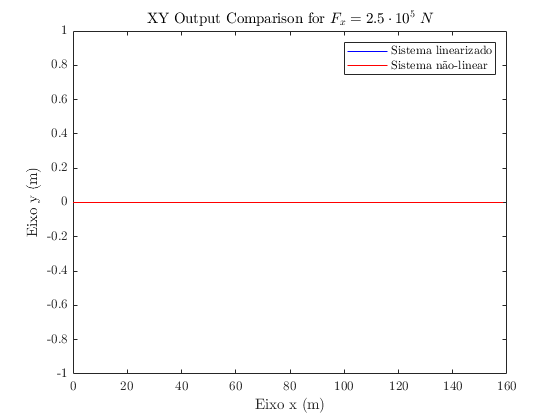

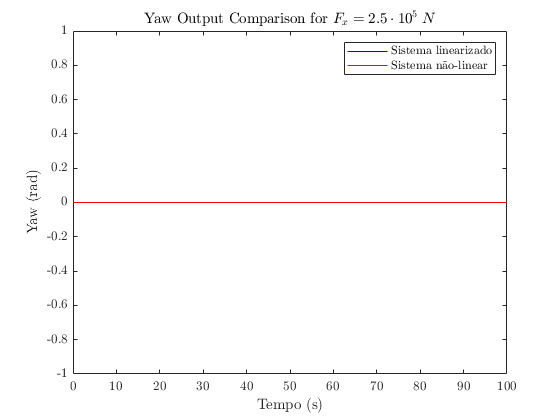

i=plota_graficos(psi_linear, yg_non_linear, xg_non_linear, xg_linear, yg_linear, psi_non_linear,i, ...
    'XY Output Comparison for $F_x=2.5\cdot10^5 \;N$',...
    'Yaw Output Comparison for $F_x=2.5\cdot10^5 \;N$');

    O gráfico espacial da trajetória do navio está de acordo

    Como esperado, dado que $F_x$ apenas influencia na aceleração em $x$, temos que não há qualquer alteração no yaw para o sistema não-linearizado. O sistema linearizado também tem o mesmo comportamento, pois a primeira coluna da matriz $B$ tem apenas um elemento não nulo e este está relacionado somente à aceleração em $x$, ou seja, não influencia rotação em yaw da embarcação.

# Teste 2

## 
$$F_x =0\;;F_{y\;} =2\ldotp 5*{10}^5 \;\;N;M_z =0$$


Found algebraic loop containing: 
nonlinear_system_angelo/equation 5/Add
nonlinear_system_angelo/equation 5/Gain
nonlinear_system_angelo/equation 6/Add2
nonlinear_system_angelo/equation 6/Product3
nonlinear_system_angelo/equation 6/Add
nonlinear_system_angelo/equation 6/Gain
nonlinear_system_angelo/equation

fx = 0;
fy = 2.5e5;
mz = 0;
[xg_linear, yg_linear, psi_linear] = sim_linear(t);
[xg_non_linear, yg_non_linear, psi_non_linear] = sim_non_linear(t);

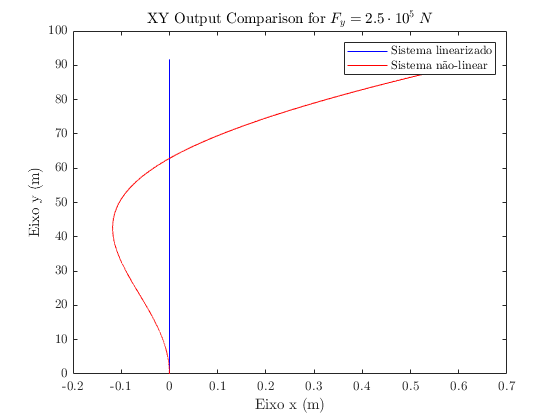

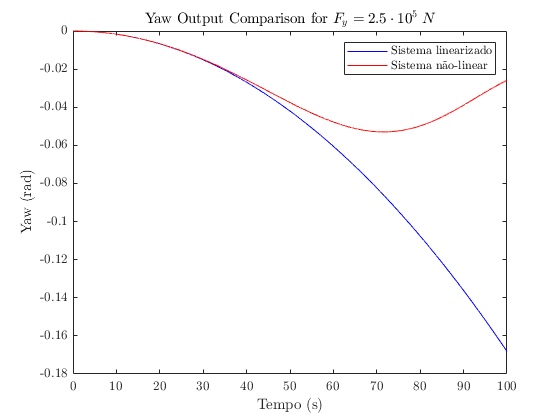

i=plota_graficos(psi_linear, yg_non_linear, xg_non_linear, xg_linear, yg_linear, psi_non_linear,i, ...
    'XY Output Comparison for $F_y=2.5\cdot10^5 \;N$',...
    'Yaw Output Comparison for $F_y=2.5\cdot10^5 \;N$');

    O gráfico espacial da trajetória do navio está de acordo com o que é esperado. Usualmente nas embarcações, há desvio do CG para o lado oposto ao que se espera dado a entrada $F_y$ positiva antes que o navio inicie, de fato, a seguir o rumo dado pela entrada. Esta característica impõe que os sistema de controle de navios prevejam esse comportamento e não entrem em "pânico" ao perceberem saída no sentido contrário, o que, usualmente, levaria o controlador à inverter a entrada imposta e, por conseguinte, não permitir a manobra do navio para o lado certo.

    O gráfico de yaw, como esperado, segue o mesmo comportamento: temos um desvio negativo do yaw e em então redirecionamento para yaw positivo, como é esperado para uma curva à esquerda dado por $F_y$ positivo, no caso da equação linearizada, dado $M_z=0$ têm-se que a aceleração angular tem direção oposta da força $F_y$ pois o de $B$ na posição (6,2) é negativo e portanto, pode-se perceber que, na realidade, o sistema linearizado mimetiza o desvio característico do sistema não-linearizado, mas ao invés de eventualmente girar em direção ao rumo desejado, este se mantém virando para o lado oposto ao da força $F_y$.

# Teste 3

## 
$$F_x =0\;;F_{y\;} =0\;;M_z =1*{10}^7 \;N\ldotp m$$


Found algebraic loop containing: 
nonlinear_system_angelo/equation 5/Add
nonlinear_system_angelo/equation 5/Gain
nonlinear_system_angelo/equation 6/Add2
nonlinear_system_angelo/equation 6/Product3
nonlinear_system_angelo/equation 6/Add
nonlinear_system_angelo/equation 6/Gain
nonlinear_system_angelo/equation

fx = 0;
fy = 0;
mz = 1e7;
[xg_linear, yg_linear, psi_linear] = sim_linear(t);
[xg_non_linear, yg_non_linear, psi_non_linear] = sim_non_linear(t);

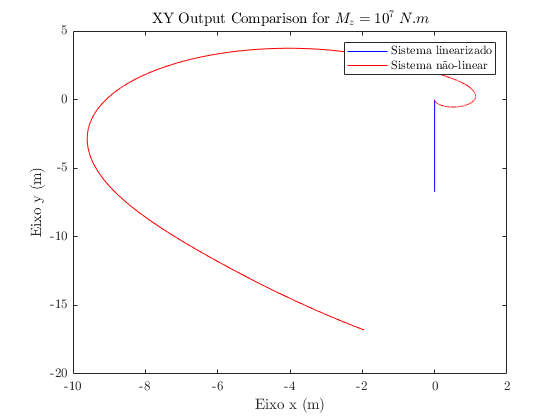

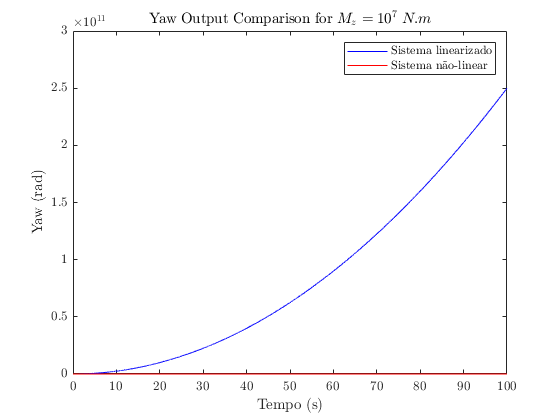

i=plota_graficos(psi_linear, yg_non_linear, xg_non_linear, xg_linear, yg_linear, psi_non_linear,i, ...
    'XY Output Comparison for $M_z=10^7 \;N.m$',...
    'Yaw Output Comparison for $M_z=10^7 \;N.m$');

    O gráfico espacial da trajetória do navio para o sistema não-linearizado está de acordo com o que se espera dada a única entrada não nula sendo $M_z$ gerando momento em yaw. Dada a equação (6), temos que há giro imediato logo no início da trajetória e no sentido positivo de yaw. Com o aumento gradativo do yaw, teremos valores não nulos para as derivadas de $u$ e $v$ que então resultam na espiral observada no *plot*. Para o sistema não linearizado, claramente percebemos que o momento em $z$ apenas influencia $\dot{v}$ e que, por esse motivo, apenas observaremos deslocamento em $y$ e no sentido contrário ao sinal do momento. Como no sistema linearizado não há correlação entre $\dot{u}$ e $M_z$ a coordenada $x$ se manterá constante.

    Para o gráfico de yaw, para o sistema linearizado, como a aceleração tem relação de proporcionalidade com a entrada $M_z$, haja vista que nesse teste essa entrada é constante, a velocidade angular será linear e então teremos uma posição angular quadrática, como é previsto.

    Neste *plot* comparativo, não é possível avaliar o comportamento do sistema não-linearizado apropriadamente dado que o sitema linearizado "explode" muito rápido. Num gráfico somente com o sistema não-linearizado, poderemos averiguar seu comportamento.

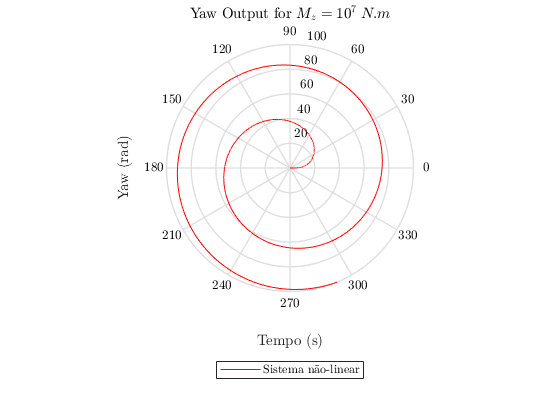

polar(psi_non_linear.Data,psi_non_linear.Time,'r');
    title('Yaw Output for $M_z=10^7 \; N.m$','Interpreter','latex');
    xlabel('Tempo (s)');
    ylabel('Yaw (rad)');
    legend('Sistema n\~ao-linear','Location','southoutside')

    i= i+1;

    Com este gráfico, percebe-se que o comportamento do sistema não-linearizado está de acordo com o esperado: dado momento constante, teremos um movimento em espiral do navio ao longo do tempo.

# Teste 4

## 
$$F_x =2\ldotp 5*{10}^5 \;N;F_{y\;} =2\ldotp 5*{10}^5 \;\;N;M_z =0$$


Found algebraic loop containing: 
nonlinear_system_angelo/equation 5/Add
nonlinear_system_angelo/equation 5/Gain
nonlinear_system_angelo/equation 6/Add2
nonlinear_system_angelo/equation 6/Product3
nonlinear_system_angelo/equation 6/Add
nonlinear_system_angelo/equation 6/Gain
nonlinear_system_angelo/equation

fx = 2.5e5;
fy = 2.5e5;
mz = 0;
[xg_linear, yg_linear, psi_linear] = sim_linear(t);
[xg_non_linear, yg_non_linear, psi_non_linear] = sim_non_linear(t);

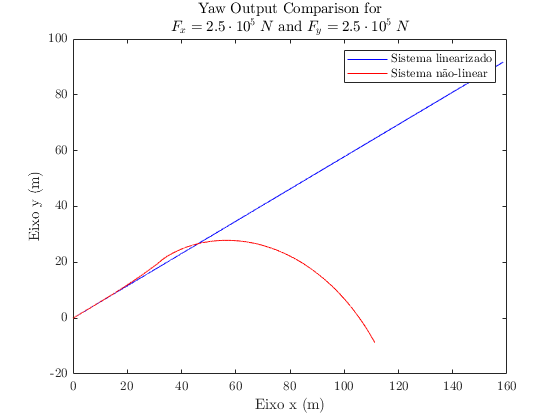

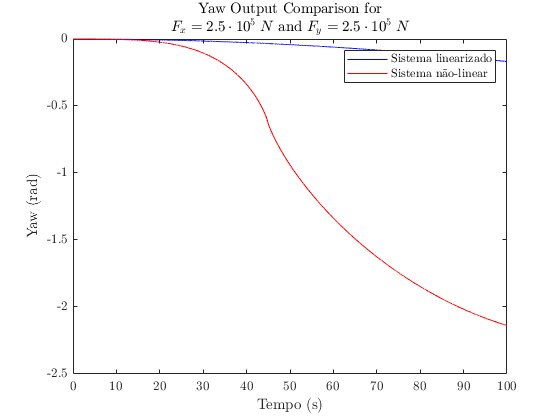

i=plota_graficos(psi_linear, yg_non_linear, xg_non_linear, xg_linear, yg_linear, psi_non_linear,i, ...
    '\begin{tabular}{c} Yaw Output Comparison for \\ $F_x=2.5\cdot10^5 \;N$ and $F_y=2.5\cdot10^5 \;N$\end{tabular}',...
    '\begin{tabular}{c} Yaw Output Comparison for \\ $F_x=2.5\cdot10^5 \;N$ and $F_y=2.5\cdot10^5 \;N$\end{tabular}');

O gráfico espacial da trajetória do navio está de acordo

# Teste 5

## 
$$F_x =2\ldotp 5*{10}^5 \;\;N\;;F_{y\;} =2\ldotp 5*{10}^5 \;\;N;M_z =1*{10}^7 \;N\ldotp m\;$$


Found algebraic loop containing: 
nonlinear_system_angelo/equation 5/Add
nonlinear_system_angelo/equation 5/Gain
nonlinear_system_angelo/equation 6/Add2
nonlinear_system_angelo/equation 6/Product3
nonlinear_system_angelo/equation 6/Add
nonlinear_system_angelo/equation 6/Gain
nonlinear_system_angelo/equation

fx = 2.5e5;
fy = 2.5e5;
mz = 1e7;
[xg_linear, yg_linear, psi_linear] = sim_linear(t);
[xg_non_linear, yg_non_linear, psi_non_linear] = sim_non_linear(t);

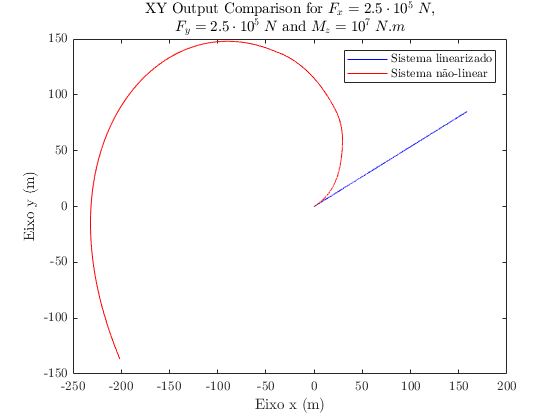

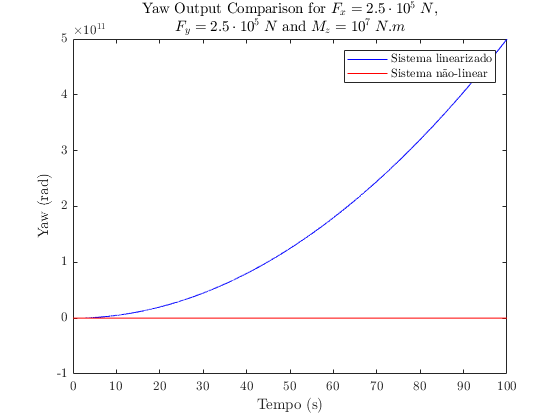

i=plota_graficos(psi_linear, yg_non_linear, xg_non_linear, xg_linear, yg_linear, psi_non_linear,i, ...
    '\begin{tabular}{c} XY Output Comparison for $F_x=2.5\cdot10^5 \;N$,\\ $F_y=2.5\cdot10^5 \;N$ and $M_z=10^7 \;N.m$\end{tabular}',...
    '\begin{tabular}{c} Yaw Output Comparison for $F_x=2.5\cdot10^5 \;N$,\\ $F_y=2.5\cdot10^5 \;N$ and $M_z=10^7 \;N.m$\end{tabular}');

    O gráfico espacial da trajetória do navio para o sistema não-linearizado está de acordo com o esperado, pois como foi observado anteriormente, no teste 3 apenas com $M_z >0$ obtivemos uma trajetória "rápida" no sentido positivo do yaw e no teste 4, com a sobreposição de ambos $F_x> 0$ e $F_y > 0$ obtivemos uma trajetória para o sentido negativo do yaw e mais lenta que a do teste 3. Portanto, quando aplicamos as três entradas juntas, dado que a magnitude do momento é maior que a sobreposição das forças lineares temos novamente uma espiral em yaw positivo contudo, mais lenta que no teste 3, pois as entradas lineares oferecem resistência à esse movimento.

    Quanto ao sistema linearizado, podemos ver que também à sobreposição dos comportamentos observados no teste 3 e 4. Há um movimento diagonal positivo em ambos os eixos contudo o deslocamento em $y$ sofre resistência dado que momento positivo nesse sistema resulta em deslocamento no sentido negativo de $y$.

    Como ocorreu no teste anterior, a análise do comportamento do sistema não-linearizado deve ser feito num *plot* à parte. Para o *output* do sistema linearizado, pode-se perceber que o comportamento relativo ao teste 3 é domina o observado no teste 4 dado que aquele tem magnitude maior que esse.    

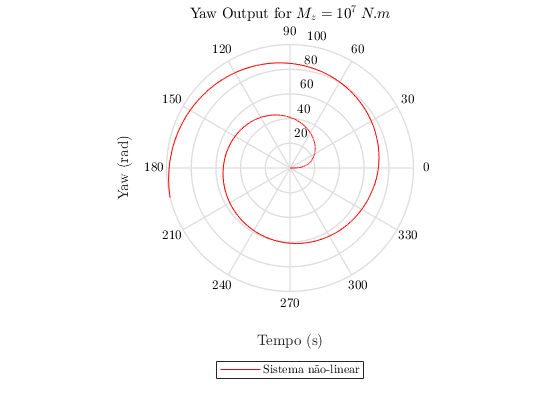

polar(psi_non_linear.Data,psi_non_linear.Time,'r');
    title('Yaw Output for $M_z=10^7 \; N.m$','Interpreter','latex');
    xlabel('Tempo (s)');
    ylabel('Yaw (rad)');
    legend('Sistema n\~ao-linear','Location','southoutside')

    Com esse *plot* podemos perceber que o movimento em espiral fora de fato retardado uma vez que o yaw resultante da aplicação das duas forças lineares é negativo e o resultante da aplicação do momento é positivo. Como a influência do momento é maior, teremos ainda movimento em yaw positivo, contudo com resistência se comparado com o teste 3.